%%%% Estimation of value of PI using montecarlo method

%%%% Define a unit circle inscribed in a square with side = 2units.

N = 100000; %% Number of samples/darts
xy = 2*rand(N,2) - 1;
xy(:,3) = xy(:,1).*xy(:,1) + xy(:,2).*xy(:,2);
xy(xy(:,3) > 1, 3) = -1;
xy(xy(:,3) ~= -1, 3) = 1;
xy(xy(:,3) == -1, 3) = 0;

valuePI = 4*sum(xy(:,3))/N

valuePI = 3.1378

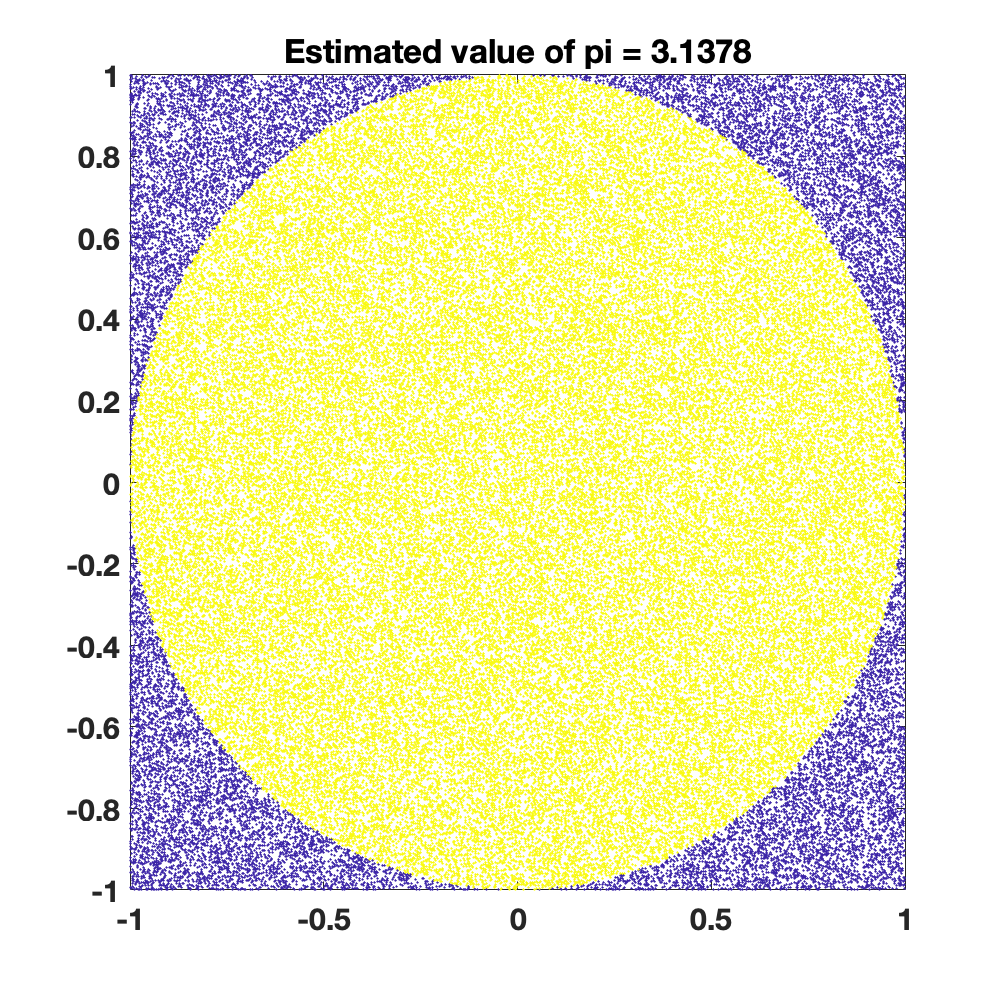


figure();
refresh
set(gcf, 'position', [10, 10, 500, 500])

scatter(xy(:,1), xy(:,2), 2, xy(:,3), 'filled')
set(gca, 'fontsize', 15, 'FontWeight', 'bold')
box on
title(sprintf('Estimated value of pi = %.4f', valuePI))

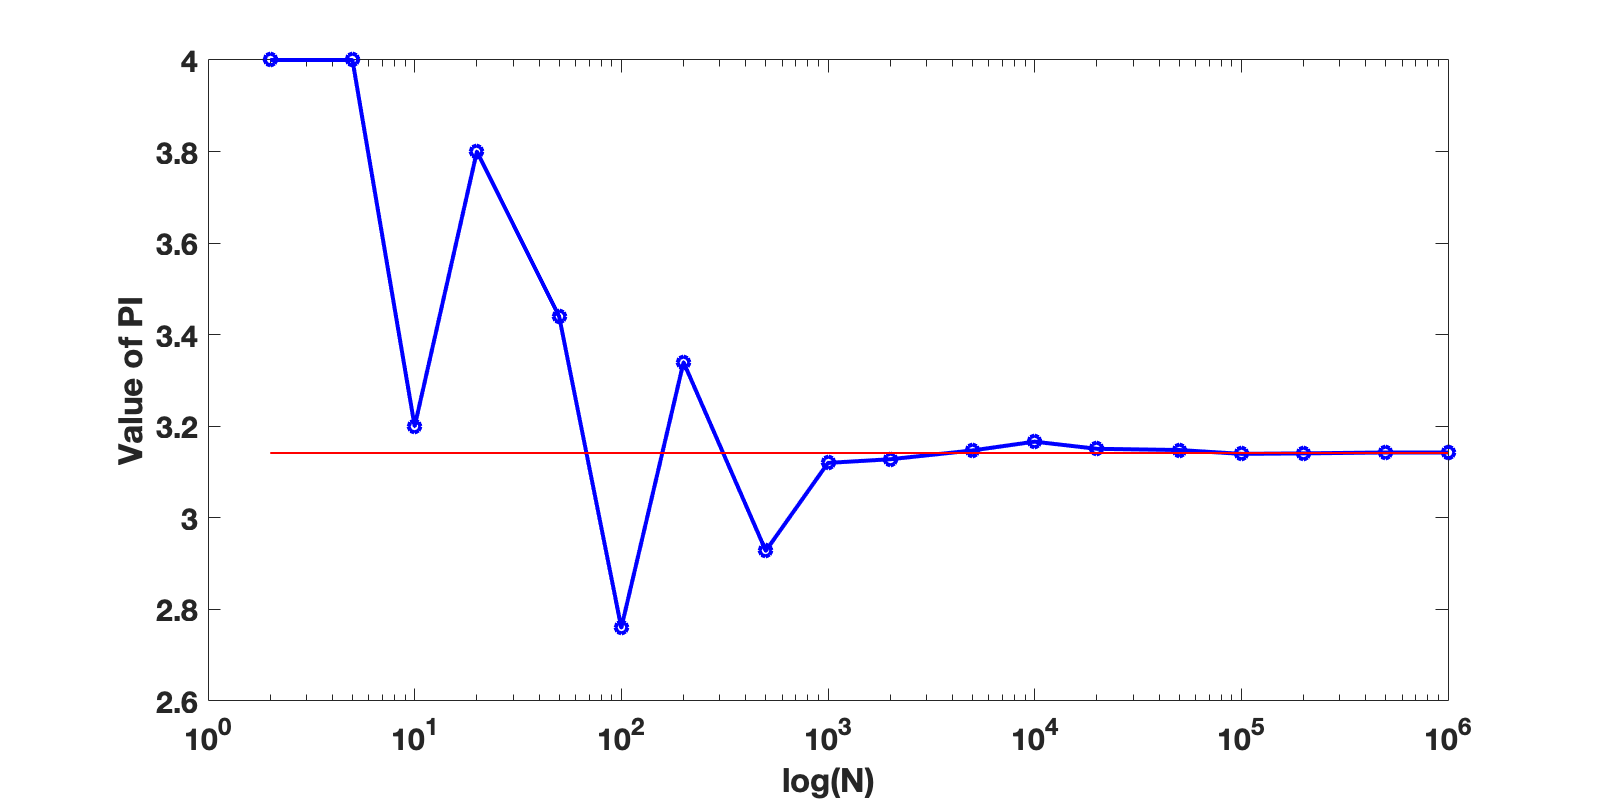

%%%% Convergence w.r.t sample size

a = 1:6;
nVec = 10.^a;
nVec = sort([nVec, nVec/2, nVec/5]);
piValues = zeros(length(nVec), 1);
for i = 1 : length(nVec)
    
    xy = 2*rand(nVec(i),2) - 1;
    xy(:,3) = xy(:,1).*xy(:,1) + xy(:,2).*xy(:,2);
    xy(xy(:,3) > 1, 3) = -1;
    xy(xy(:,3) ~= -1, 3) = 1;
    xy(xy(:,3) == -1, 3) = 0;
    
    piValues(i) = 4*sum(xy(:,3))/nVec(i);
end

figure();
refresh
set(gcf, 'position', [10, 10, 800, 400])
semilogx(nVec, piValues, 'o-b', 'LineWidth', 2)
hold on
semilogx(nVec, pi + zeros(1,length(nVec)), 'r', 'LineWidth', 1)
hold off
box on
set(gca, 'fontsize', 15, 'FontWeight', 'bold')
xlabel('log(N)')
ylabel('Value of PI')